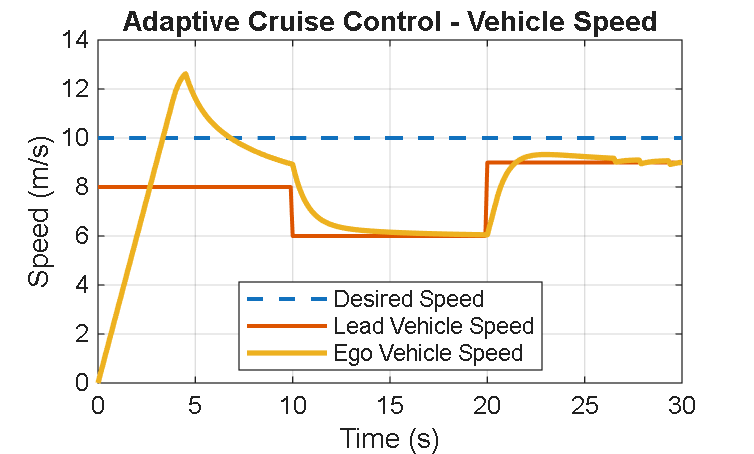

%% ============================================================
%  ADAPTIVE CRUISE CONTROL USING MATLAB
%  Vehicle Speed and Safe Distance Control
% =============================================================
clc;
clear;
close all;
%% ============================================================
% 1. VEHICLE PARAMETERS
% ============================================================
m = 1000;              % Vehicle mass (kg)
b = 50;                % Vehicle drag coefficient
desiredSpeed = 10;     % Desired speed (m/s)
%% ============================================================
% 2. SIMULATION PARAMETERS
% ============================================================
dt = 0.1;              % Simulation time step
simulationTime = 30;   % Simulation duration
time = 0:dt:simulationTime;
%% ============================================================
% 3. LEAD VEHICLE PARAMETERS
% ===========================================================
initialDistance = 30;  % Initial distance between vehicles (m)
minimumDistance = 8;   % Minimum safe distance (m)
timeGap = 1.5;         % Desired time gap (seconds)
%% ============================================================
% 4. INITIALIZE VARIABLES
% ============================================================
egoSpeed = zeros(size(time));
leadSpeed = zeros(size(time));
distance = zeros(size(time));
safeDistance = zeros(size(time));
targetSpeed = zeros(size(time));
acceleration = zeros(size(time));
%% Initial conditions
egoSpeed(1) = 0;
distance(1) = initialDistance;
%% ============================================================
% 5. LEAD VEHICLE SPEED PROFILE
% ============================================================
for k = 1:length(time)

    if time(k) < 10

        % Lead vehicle travels at 8 m/s
        leadSpeed(k) = 8;

    elseif time(k) < 20

        % Lead vehicle slows down
        leadSpeed(k) = 6;

    else

        % Lead vehicle accelerates again
        leadSpeed(k) = 9;

    end

end

%% ============================================================
% 6. PI CONTROLLER PARAMETERS
% ============================================================

Kp = 1.5;

Ki = 0.3;

integralError = 0;

%% ============================================================
% 7. ACC SIMULATION
% ============================================================

for k = 1:length(time)-1

    %% --------------------------------------------------------
    % Calculate safe following distance
    % ---------------------------------------------------------

    safeDistance(k) = minimumDistance + ...
                      timeGap * egoSpeed(k);

    %% --------------------------------------------------------
    % Calculate distance error
    % ---------------------------------------------------------

    distanceError = distance(k) - safeDistance(k);

    %% --------------------------------------------------------
    % ACC DECISION LOGIC
    % ---------------------------------------------------------

    if distanceError > 10

        % Lead vehicle is far enough away
        % Maintain desired speed

        targetSpeed(k) = desiredSpeed;

    elseif distanceError >= 0

        % Lead vehicle is approaching
        % Follow lead vehicle if necessary

        targetSpeed(k) = min(desiredSpeed, ...
                             leadSpeed(k));
    elseif distanceError > -3

        % Vehicle is slightly inside the safe-distance region
        % Reduce speed below the lead vehicle speed

        targetSpeed(k) = max(0, leadSpeed(k) - 1);


    else

        % Vehicle is too close
        % Match lead vehicle speed

        targetSpeed(k) = max(0, leadSpeed(k) - 2);


    end

    %% --------------------------------------------------------
    % PI CONTROLLER
    % ---------------------------------------------------------

    speedError = targetSpeed(k) - egoSpeed(k);

    integralError = integralError + ...
                    speedError * dt;

    controlSignal = Kp * speedError + ...
                    Ki * integralError;

    %% --------------------------------------------------------
    % Vehicle dynamics
    % ---------------------------------------------------------

    acceleration(k) = controlSignal;
       

    %% Limit acceleration

    acceleration(k) = max(min(acceleration(k), 3), -4);

    %% --------------------------------------------------------
    % Update ego vehicle speed
    % ---------------------------------------------------------

    egoSpeed(k+1) = egoSpeed(k) + ...
                    acceleration(k) * dt;

    %% Prevent negative speed

    egoSpeed(k+1) = max(egoSpeed(k+1), 0);

    %% --------------------------------------------------------
    % Update distance between vehicles
    % ---------------------------------------------------------

    relativeSpeed = leadSpeed(k) - egoSpeed(k);

    distance(k+1) = distance(k) + ...
                    relativeSpeed * dt;

    %% Prevent negative distance

    distance(k+1) = max(distance(k+1), 0);

end

%% Final values

safeDistance(end) = minimumDistance + ...
                    timeGap * egoSpeed(end);

targetSpeed(end) = targetSpeed(end-1);

acceleration(end) = acceleration(end-1);

%% ============================================================
% 8. VEHICLE SPEED GRAPH
% ============================================================

figure

plot(time, desiredSpeed * ones(size(time)), '--', ...
     'LineWidth', 1.5)

hold on

plot(time, leadSpeed, ...
     'LineWidth', 1.5)

plot(time, egoSpeed, ...
     'LineWidth', 2)

grid on

xlabel('Time (s)')
ylabel('Speed (m/s)')

title('Adaptive Cruise Control - Vehicle Speed')

legend('Desired Speed', ...
       'Lead Vehicle Speed', ...
       'Ego Vehicle Speed', ...
       'Location', 'best')

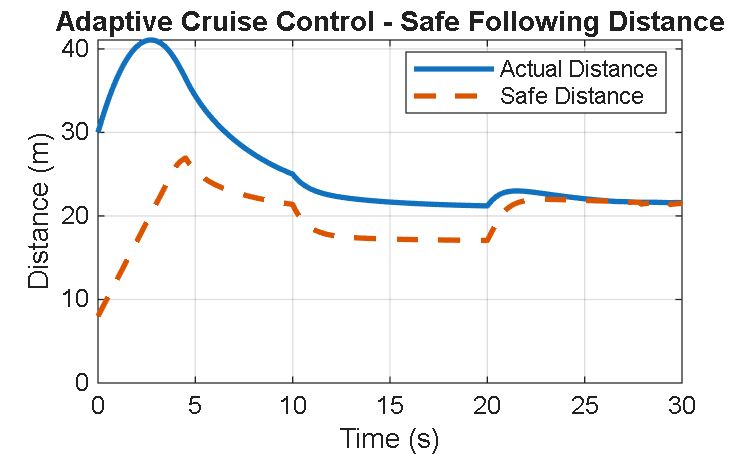


%% ============================================================
% 9. DISTANCE GRAPH
% ============================================================

figure

plot(time, distance, ...
     'LineWidth', 2)

hold on

plot(time, safeDistance, '--', ...
     'LineWidth', 2)

grid on

xlabel('Time (s)')
ylabel('Distance (m)')

title('Adaptive Cruise Control - Safe Following Distance')

legend('Actual Distance', ...
       'Safe Distance', ...
       'Location', 'best')

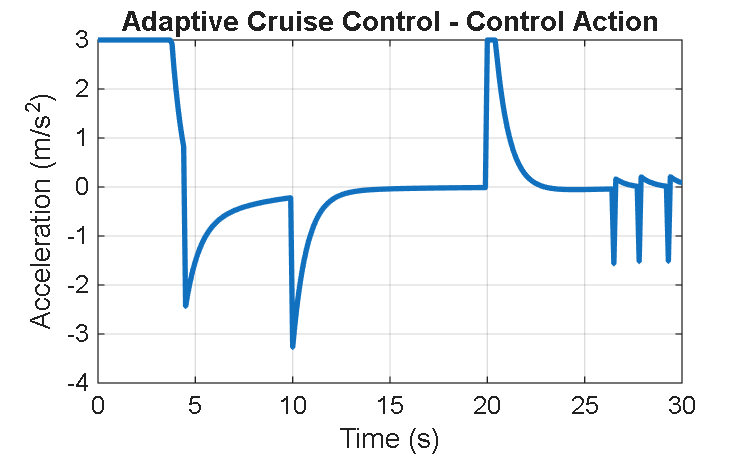


%% ============================================================
% 10. ACC CONTROL ACTION
% ============================================================

figure

plot(time, acceleration, ...
     'LineWidth', 2)

grid on

xlabel('Time (s)')
ylabel('Acceleration (m/s^2)')

title('Adaptive Cruise Control - Control Action')

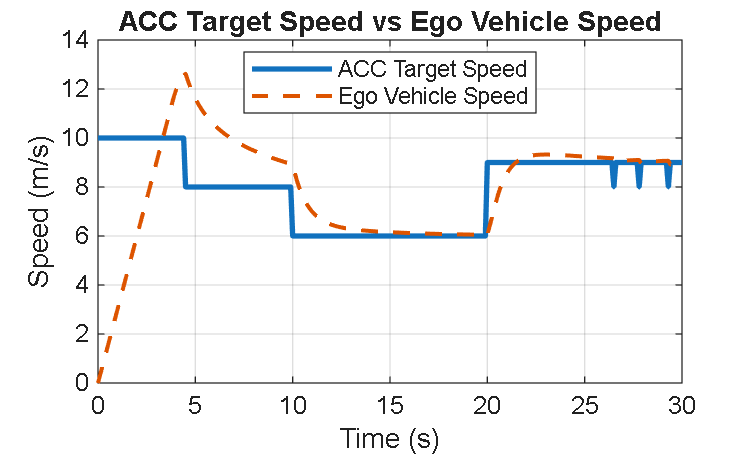


%% ============================================================
% 11. TARGET SPEED
% ============================================================

figure

plot(time, targetSpeed, ...
     'LineWidth', 2)

hold on

plot(time, egoSpeed, '--', ...
     'LineWidth', 1.5)

grid on

xlabel('Time (s)')
ylabel('Speed (m/s)')

title('ACC Target Speed vs Ego Vehicle Speed')

legend('ACC Target Speed', ...
       'Ego Vehicle Speed', ...
       'Location', 'best')


%% ============================================================
% 12. DISPLAY RESULTS
% ============================================================

fprintf('\n');
fprintf('=============================================\n');

fprintf('       ADAPTIVE CRUISE CONTROL RESULTS\n');

       ADAPTIVE CRUISE CONTROL RESULTS


fprintf('=============================================\n');


fprintf('Desired Speed            = %.2f m/s\n', ...
        desiredSpeed);

Desired Speed            = 10.00 m/s



fprintf('Final Ego Vehicle Speed  = %.2f m/s\n', ...
        egoSpeed(end));

Final Ego Vehicle Speed  = 9.01 m/s



fprintf('Final Lead Vehicle Speed = %.2f m/s\n', ...
        leadSpeed(end));

Final Lead Vehicle Speed = 9.00 m/s



fprintf('Final Vehicle Distance   = %.2f m\n', ...
        distance(end));

Final Vehicle Distance   = 21.61 m



fprintf('Final Safe Distance      = %.2f m\n', ...
        safeDistance(end));

Final Safe Distance      = 21.51 m



fprintf('Minimum Vehicle Distance = %.2f m\n', ...
        min(distance));

Minimum Vehicle Distance = 21.21 m



fprintf('=============================================\n');


%% ============================================================
% 13. SAFETY CHECK
% ============================================================

safetyTolerance = 0.5;     % Allow 0.5 m numerical tolerance

if all(distance >= safeDistance - safetyTolerance)

    disp('ACC Safety Check: Safe following distance maintained.');

else

    disp('ACC Safety Check: Safe distance was violated.');

end

ACC Safety Check: Safe following distance maintained.



%% ============================================================
% 14. PROJECT INFORMATION
% ============================================================

disp(' ');

disp('=============================================');

disp(' Adaptive Cruise Control System');

 Adaptive Cruise Control System


disp(' MATLAB and Simulink Project');

 MATLAB and Simulink Project


disp('=============================================');

t_lead = (0:0.1:30)';

lead_speed = zeros(size(t_lead));

lead_speed(t_lead < 10) = 8;
lead_speed(t_lead >= 10 & t_lead < 20) = 6;
lead_speed(t_lead >= 20) = 9;

lead_vehicle_data = [t_lead lead_speed];